%sample and save data from the audio file
[data1, fs1] = audioread('03 - The Andy Griffith Show(1).mp3');

N1 = 1;

%print sampling frequency of the audio file
disp("The sampling frequency of Data1 using N = " + N1 + " is " + fs1/N1 + " Hz")

The sampling frequency of Data1 using N = 1 is 44100 Hz



%print the sampling period of the audio file
Ts1 = 1/fs1;
disp("The sampling period of Data2 N = " + N1 + " is " + Ts1*N1 + " seconds/sample") 

The sampling period of Data2 N = 1 is 2.2676e-05 seconds/sample




%define a subset of the sound file data
data1_channel1 = data1(:,1); %save the first column of the data, 

%54.167 seconds of data = 2388720 samples * (2.676e-05) seconds/sample =
%54.167 seconds
%data_channel1short = data_channel1(1:(length(data_channel1)/10),1);

data1_channel1_excerpt = data1_channel1(70000:70200); %save an excerpt of the data
data1_channel1_excerpt2 = data1_channel1(70200:70400); %save a second excerpt of the daya


%plot the discrete-time sinusoid data
n1 = 1:length(data1_channel1_excerpt); %x-axis Samples. Points n of x[n]
time_vector1 = n1 * Ts1; %a vector with the time at every data point x[n]

%first subplot that displays a subset of the data
figure(1)
subplot(2,1,1), stem(n1, data1_channel1_excerpt) %create a subplot of a discrete-time sinusoid
title("Excerpt 1 of Data1 (70000:70200)"); %title
xlabel("Sample (N) taken at 1 sample every 2.2676e-05 seconds"); %xlabel
ylabel("Data read from audio file 1"); %ylabel

%second subplot that displays a different subset of the data
subplot(2,1,2), stem(n1, data1_channel1_excerpt2) %create a subplot of a discrete-time sinusoid
title("Excerpt 2 of Data1 (70200:70400)"); %title
xlabel("Sample (N) taken at 1 sample every 2.2676e-05 seconds"); %xlabel
ylabel("Data read from audio file 1"); %ylabel


%downsample the data keeping every Nth point, like as if you sampled the
%data with a sampling period that is N times bigger
downsampled_data1 = downsample(data1_channel1, N1); %downsample

%play the downsampled audio to determine the Nyquist rate/aliasing effects
%soundsc(downsampled_data1, fs1/N1)

%N1 = 12.

%Nyquist rate
%and
%fs > 2fb

%Repeat audioread, subset, subplot, downsample, sound, tabulate, short
%description of your audio

%sample and save data from the audio file
[data2, fs2] = audioread('04 - Song.m4a');

N2 = 1;

%print sampling frequency of the audio file
disp("The sampling frequency of Data2 using N = " + N2 + " is " + fs2/N2 + " Hz")

The sampling frequency of Data2 using N = 1 is 48000 Hz



%print inherant sampling frequency of the iPhone 7
disp("The inherant sampling frequency of the iPhone 7 is " + 48000 + " Hz")

The inherant sampling frequency of the iPhone 7 is 48000 Hz



%print the sampling period of the audio file
Ts2 = 1/fs2;
disp("The sampling period of Data2 using N = " + N2 + " is " + Ts2*N2+ " seconds/sample") 

The sampling period of Data2 using N = 1 is 2.0833e-05 seconds/sample


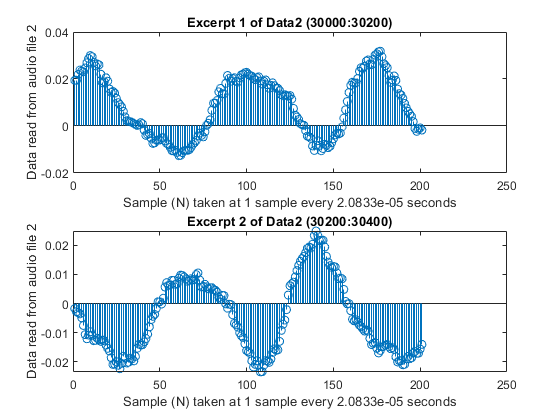


%define a subset of the sound file data
data2_channel1 = data2(:,1); %save the first column of the data, 

%10.37 seconds of data = 497999 samples * (2.0833e-05) seconds/sample =
%10.37 seconds

data2_channel1_excerpt = data2_channel1(30000:30200); %save an excerpt of the data
data2_channel1_excerpt2 = data2_channel1(30200:30400); %save a second excerpt of the daya


%plot the discrete-time sinusoid data
n2 = 1:length(data2_channel1_excerpt); %x-axis Samples. Points n of x[n]
time_vector = n2 * Ts2; %a vector with the time at every data point x[n]

%first subplot that displays a subset of the data
figure(2)
subplot(2,1,1), stem(n2, data2_channel1_excerpt) %create a subplot of a discrete-time sinusoid
title("Excerpt 1 of Data2 (30000:30200)"); %title
xlabel("Sample (N) taken at 1 sample every 2.0833e-05 seconds"); %xlabel
ylabel("Data read from audio file 2"); %ylabel

%second subplot that displays a different subset of the data
subplot(2,1,2), stem(n2, data2_channel1_excerpt2) %create a subplot of a discrete-time sinusoid
title("Excerpt 2 of Data2 (30200:30400)"); %title
xlabel("Sample (N) taken at 1 sample every 2.0833e-05 seconds"); %xlabel
ylabel("Data read from audio file 2"); %ylabel



%downsample the data keeping every Nth point, like as if you sampled the
%data with a sampling period that is N times bigger
downsampled_data2 = downsample(data2_channel1, N2); %downsample


%play the downsampled audio to determine the Nyquist rate/aliasing effects
%soundsc(downsampled_data2, fs2/N2) %N: 40 sounds like a tunnel. 25 sounds quiet

%N = 21

%Nyquist rate
%and
%fs > 2fb fb from DFT